**Problem 1. **Determine how many people have more than or equal to 30 years old using a for loop from the 'screentime.xlsx' file.

c=screentime.Age

c =    NaN
   NaN
    25
    34
    41
    24
    41
    31
    39
    48


s=0

s = 0

for i=1:length(c)
 if c(i)>=30;
    s=s+1;
 end
end
disp(s)

    71



**Problem 3.** 

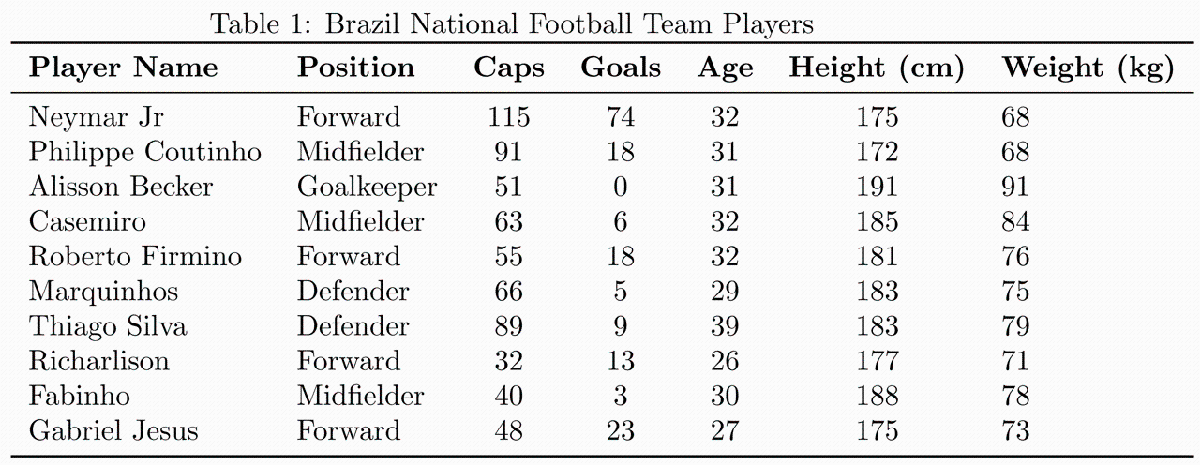

- Make this table in MATLAB.

- Find out the percentage of players in each position category.

- Calculate BMI of each player and add a new column named BMI in the existing table.

PlayerName=["Neymar Jr";"Philippe Coutinho";"ALisson Becker";"Casemiro";"Roberto Firmino";"Marquinhos";"Thiago Silva";"Richarlison";"Fabinho";"Gabriel Jesus"]

PlayerName = 10×1 string array
    "Neymar Jr"
    "Philippe Coutinho"
    "ALisson Becker"
    "Casemiro"
    "Roberto Firmino"
    "Marquinhos"
    "Thiago Silva"
    "Richarlison"
    "Fabinho"
    "Gabriel Jesus"


Position=["Forward";"MIdfielder";"Goalkeeper";"MIdfielder";"Forward";"Defender";"Defender";"Forward";"Midfielder";"Forward"]

Position = 10×1 string array
    "Forward"
    "MIdfielder"
    "Goalkeeper"
    "MIdfielder"
    "Forward"
    "Defender"
    "Defender"
    "Forward"
    "Midfielder"
    "Forward"


Caps=[115;91;51;63;55;66;89;32;40;48]

Caps =    115
    91
    51
    63
    55
    66
    89
    32
    40
    48


Goals=[74;18;0;6;18;5;9;13;3;23]

Goals =     74
    18
     0
     6
    18
     5
     9
    13
     3
    23


Age=[32;31;31;32;32;29;39;26;30;27]

Age =     32
    31
    31
    32
    32
    29
    39
    26
    30
    27


Weight=[68;68;91;84;76;75;79;71;78;73]

Weight =     68
    68
    91
    84
    76
    75
    79
    71
    78
    73


Height=[175;172;191;185;181;183;183;177;188;175]

Height =    175
   172
   191
   185
   181
   183
   183
   177
   188
   175


Team=table(PlayerName,Position,Caps,Goals,Age,Height,Weight)

Team = 10×7 table
        PlayerName           Position      Caps    Goals    Age    Height    Weight
    ___________________    ____________    ____    _____    ___    ______    ______

    "Neymar Jr"            "Forward"       115      74      32      175        68  
    "Philippe Coutinho"    "MIdfielder"     91      18      31      172        68  
    "ALisson Becker"       "Goalkeeper"     51       0      31      191        91  
    "Casemiro"             "MIdfielder"     63       6      32      185        84  
    "Roberto Firmino"      "Forward"        55      18      32      181        76  
    "Marquinhos"           "Defender"       66       5      29      183        75  
    "Thiago Silva"         "Defender"       89       9      39      183

Team.BMI=(Team.Weight.*0.453592)./(Team.Height.*0.0254)*.2

Team = 10×8 table
        PlayerName           Position      Caps    Goals    Age    Height    Weight     BMI  
    ___________________    ____________    ____    _____    ___    ______    ______    ______

    "Neymar Jr"            "Forward"       115      74      32      175        68      1.3878
    "Philippe Coutinho"    "MIdfielder"     91      18      31      172        68       1.412
    "ALisson Becker"       "Goalkeeper"     51       0      31      191        91      1.7016
    "Casemiro"             "MIdfielder"     63       6      32      185        84      1.6217
    "Roberto Firmino"      "Forward"        55      18      32      181        76      1.4997
    "Marquinhos"           "Defender"       66     

**Problem 2. ** Implement a MATLAB function to approximate the sine function using the Taylor series expansion up to a specified number of terms. The Taylor series expansion of sine function is given by:


$$\[
\sin(x) = x - \frac{{x^3}}{{3!}} + \frac{{x^5}}{{5!}} - \frac{{x^7}}{{7!}} + \cdots
\]
$$


Write a MATLAB function sin`_approx` that takes two input arguments: `x` (the angle in radians) and `terms` (the number of terms to include in the approximation). The function should return the approximate value of cosine calculated using the Taylor series expansion up to the specified number of terms.

function sin=sin_approx(x,terms)
a=x*(pi/180);

sin=0
for i=0:terms-1
    sum=(((-1)^i)/(factorial(2*i+1)))*(a^(2*i+1));
    sin=sin+sum;
end
end


